% Alvaro Gonzalez Martinez A01646343
m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;
y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

% dx = 1
h = 0.5

h = 0.5000

% define error array store the relative error at each step

x=x0:h:xf

x =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000


y=zeros(size(x))

y =      0     0     0     0     0     0     0


% m_array=zeros(size(x))
y(1) = y0

y =     10     0     0     0     0     0     0


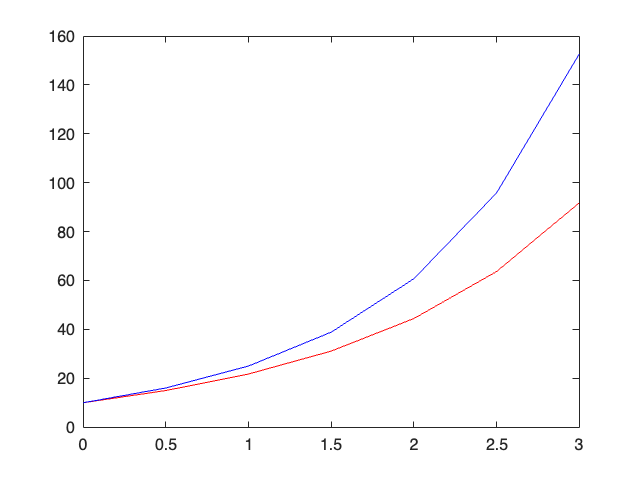

error_rel = zeros(size(x));


% inside for we need to calculate the error
for i=1:length(x)-1
    y(i+1)=y(i)+h*m(x(i),y(i));

    error_rel(i+1) = abs((yexact(x(i+1)) - y(i+1))/yexact(x(i+1)))*100; % PERCENTAGE
end
error_rel_euler = error_rel;

% plot(x,y, 'r')
plot(x,y, 'r')
hold on
plot(x,yexact(x), 'b')
hold off

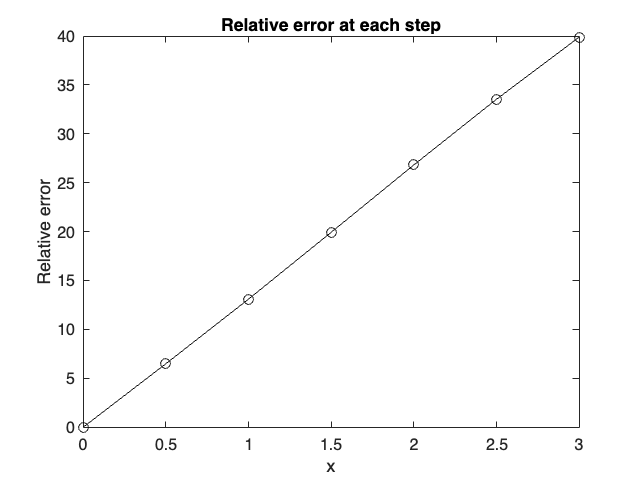


figure;
plot(x, error_rel, 'k-o');
xlabel('x');
ylabel('Relative error');
title('Relative error at each step');

% First improvement over Eulers method
m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;
y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

% dx = 1
h = 0.5

h = 0.5000

% define error array store the relative error at each step

x=x0:h:xf

x =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000


y=zeros(size(x))

y =      0     0     0     0     0     0     0


% m_array=zeros(size(x))
y(1) = y0

y =     10     0     0     0     0     0     0


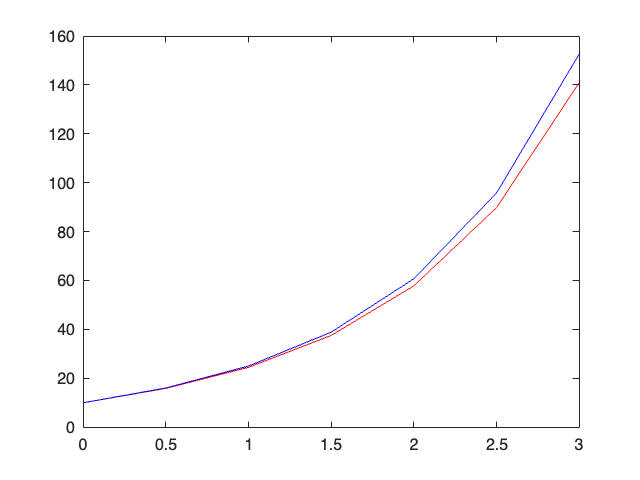

error_rel = zeros(size(x));


% inside for we need to calculate the error
for i=1:length(x)-1
    % mi current slope
    mi = m(x(i), y(i));
    % Calculate next prediction
    y_predict = y(i) + h * mi;
    % Calculate next slope
    mf = m(x(i+1), y_predict);
    % average
    m_avg = (mi + mf) / 2;
    % next aproach
    y(i+1) = y(i) + h * m_avg;


    error_rel(i+1) = abs((yexact(x(i+1)) - y(i+1))/yexact(x(i+1)))*100; % PERCENTAGE
end
error_rel_heun = error_rel;

% plot(x,y, 'r')
plot(x,y, 'r')
hold on
plot(x,yexact(x), 'b')
hold off

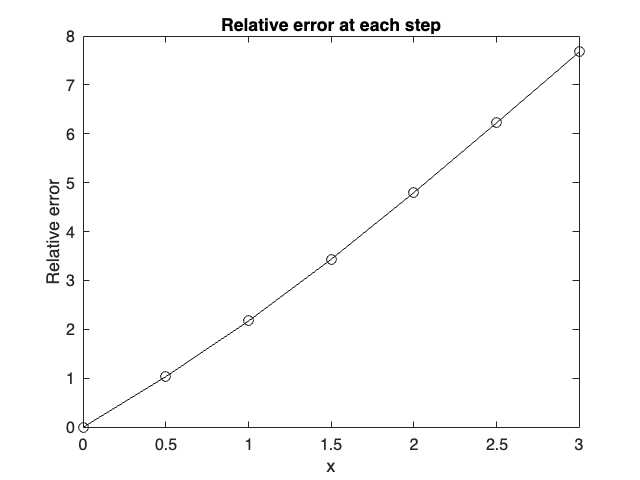


figure;
plot(x, error_rel, 'k-o');
xlabel('x');
ylabel('Relative error');
title('Relative error at each step');

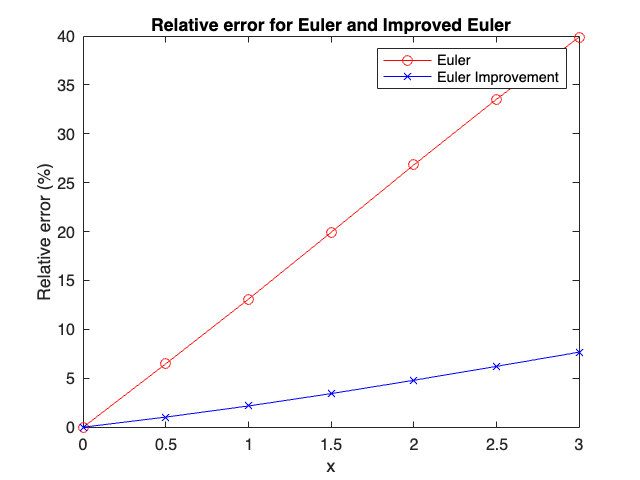


figure;
plot(x, error_rel_euler, 'r-o', 'DisplayName', 'Euler');
hold on;
plot(x, error_rel_heun, 'b-x', 'DisplayName', 'Euler Improvement');
xlabel('x');
ylabel('Relative error (%)');
title('Relative error for Euler and Improved Euler');
legend show;
hold off;